## Part (i): Limiting O2  Uptake

% Adding to the PATH and clr screen 
%addpath(genpath('nanoCobratoolbox_(1)'))
clc, clearvars;

% Loading the Geobacillus icigianus model
model = readCbModel('Geobacillus_icigianus_model.xml');


% Changing the oxygen uptake rate
o2_uptake = findRxnIDs(model, 'EX_o2_e');
original_o2_uptake = model.lb(o2_uptake);
model.lb(o2_uptake) = -0.03125; % note: for future .lb is easier than ChangeRxnBounds
% Finding the growth rate under the given oxygen conditions
sol = optimizeCbModel(model);
o2_growth_rate = sol.f;
fprintf('Growth rate with %.4f mmol gDC/Wh O2 uptake rate = %.4f /hour \n', model.lb(o2_uptake), o2_growth_rate)

Growth rate with -0.0312 mmol gDC/Wh O2 uptake rate = 0.4133 /hour 



% Restoring the original oxygen uptake rate 
% For subsequent parts 
model.lb(o2_uptake) = original_o2_uptake;


## Part (ii): Growth Rate with Alt. C Sources

% Finding the sugar uptake reactions
glc_uptake = findRxnIDs(model, 'EX_glc__D_e');
arab_uptake = findRxnIDs(model, 'EX_arab__L_e');
xyl_uptake = findRxnIDs(model, 'EX_xyl__D_e');

% Finding the original uptake rates of the sugars
original_glc_uptake = model.lb(glc_uptake);
original_arab_uptake = model.lb(arab_uptake);
original_xyl_uptake = model.lb(xyl_uptake);

% Setting the uptake rate of glucose to be 0, i.e., glucose is absent in the medium
model.lb(glc_uptake) = 0;

% ___________Simuluation with L-arabinose only__________________ % 
model.lb(arab_uptake) = -20;
model.lb(xyl_uptake) = 0;
sol = optimizeCbModel(model);
arab_growth_rate = sol.f;
fprintf('\nGrowth rate on arabinose in absence of glucose = %.4f /hour', arab_growth_rate)


Growth rate on arabinose in absence of glucose = 0.5238 /hour



% ________Simulation with D-xylose only _________ % 
model.lb(xyl_uptake) = -19;
model.lb(arab_uptake) = 0;
sol = optimizeCbModel(model);
xyl_growth_rate = sol.f;
fprintf('\nGrowth rate on xylose in absence of glucose = %.4f / hourn', xyl_growth_rate)


Growth rate on xylose in absence of glucose = 0.4976 / hourn

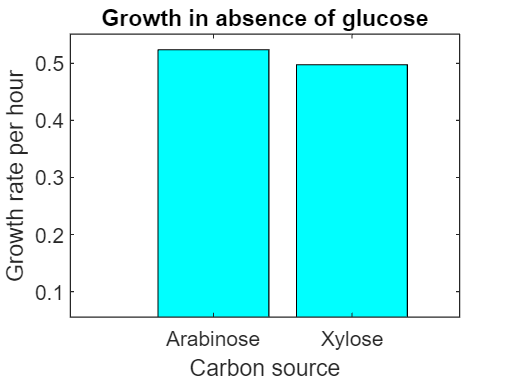


% _______Comparision of Growth Rates_____________%
% Plotting the growth rates as a bar graph
bar([arab_growth_rate, xyl_growth_rate], 'grouped', 'cyan');
title('Growth in absence of glucose');
xlabel('Carbon source');
ylabel('Growth rate per hour');
xticklabels({'Arabinose', 'Xylose'});

fprintf('Therefore, at these uptake rates, Arabinose is a marginally better Carbon source\n')

Therefore, at these uptake rates, Arabinose is a marginally better Carbon source



% Restore og uptake rates in the model for Part (iii)
model.lb(glc_uptake) = original_glc_uptake;
model.lb(arab_uptake) = original_arab_uptake;
model.lb(xyl_uptake) = original_xyl_uptake;

## Part (iii): Maximise Butandiol Production

% Goal is to max butanediol production and max biomass, i.e. simultaneous
% maximisation 
% Therefore, problem can be cast as Flux scanning based on enforced objective flux. FSEOF
% Function taken from: https://github.com/RamanLab/co-FSEOF/blob/main/FSEOF.m
[~, IncFlux, DecFlux] = FSEOF(model,'EX_btd_RR_e', {}, {});

10: infeasible solution at Venfprdt = 17.454545 




% Identify genes that can be overexpressed or deleted based on reactions predicted by FSEOF
overexpression_genes = findGenesFromRxns(model, IncFlux(:, end));
overexpression_genes = unique(vertcat(overexpression_genes{:})); % remove overexp repeats 

deletion_genes = findGenesFromRxns(model, DecFlux(:, end));
deletion_genes = unique(vertcat(deletion_genes{:})); % remove deletn repeats

fprintf('RESULTS FOR PART (iii) \n')

RESULTS FOR PART (iii) 


fprintf('%u Overexpression targets found for improving 2,3-butanediol production.\n', size(IncFlux, 1))

8 Overexpression targets found for improving 2,3-butanediol production.


fprintf('%u gene overexpression targets found for improving 2,3-butanediol production: See var overexpression_genes\n', size(overexpression_genes, 1))

16 gene overexpression targets found for improving 2,3-butanediol production: See var overexpression_genes


fprintf('%u reaction knockout targets found for improving 2,3-butanediol production\n', size(DecFlux, 1))

395 reaction knockout targets found for improving 2,3-butanediol production


fprintf('%u gene knockout targets found for improving 2,3-butanediol production\n', size(deletion_genes, 1))

576 gene knockout targets found for improving 2,3-butanediol production
